# Taratura ottima con vincoli robusti

Determinare $C(s)$ in modo che soddisfi vincoli in frequenza e ottimizi una cifra di merito.

Si possono scegliere tanti vincoli e cifre di merito, ma la struttura base rimane simile.

In quest'esempio il controllore è un PID con filtro sull'azione derivativa


$$C(s)=PID(s)=K_p+\frac{K_i}{s}+\frac{K_d\cdot s}{T_fs+1}$$


il processo è la funzione di trasferimento, in questo caso coppia - velocità lato motore

clear all;close all;clc;
load modello_jnt2.mat
sys_vel_motore=tf(modello_giunto(2,1));

Inserisco il filtro notch (volendo si può pensare di ottimizzare anche i coefficienti del filtro

wn=290;
xci_z=0.1; %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p=0.7;
s=tf('s');
notch=(s^2+2*xci_z*wn*s+wn^2)/(s^2+2*xci_p*wn*s+wn^2);
P=sys_vel_motore*notch;

La cifra di merito è


$$J=\left( \omega_c - \omega_{c,des}\right)^2$$


(alternativa $J=-\omega_c$ massimizzare la pulsazione di taglio)

con $\omega_c$ la frequenza (pulsazione) di taglio, e $\omega_{c,des}$ il valore desiderato.

Le incognite del problema sono $x=[K_p,\;K_i,\;K_d,\;T_f]$

wc_des=70;
J=@(x)pidvel_cost_function(x,P,wc_des);

I vincoli sono (potete modificarli, aggiungerne, toglierne)

- massima sensitività $MS<1.4$ per garantire la robustezza (1.4 molto robusto, 2 poco robusto ma aggressivo)

- La funzione di anello chiuso $F$ deve avere modulo limitato con $\omega\geq\omega_h$

- La funzione fra disturbo sul carico e l'uscita deve modulo limitato quando $\omega\leq\omega_l$

- Il margine di fase deve essere almeno 60°

Per calcolare in maniera corretta $MS$ passo alla funzione anche il vettore delle pulsazioni naturali che voglio testare

MS=1.4;
wh=2000;
Fh_max=0.1;
wl=0.1;
Dh_max=0.1;
PM_min=60;

w_vector=logspace(-2,4,1e3)'; % [10^0,10^4]
w_vector=sort([w_vector;wl;wh]);

nlcon=@(x)pidvel_constraints(x,P,w_vector,MS,wh,Fh_max,wl,Dh_max,PM_min);

Risolvo il problema con GlobalSearch, la soluzione è *globale*.

gs = GlobalSearch('Display','iter');
x0=[1,1,0,10];

problem = createOptimProblem('fmincon','x0',x0,...
    'objective',J,'lb',[0.01,0.01,0,0.001],'ub',[10000,10000,10000,100],'nonlcon',nlcon);
x = run(gs,problem)

 Num Pts                 Best       Current    Threshold        Local        Local                 
Analyzed  F-count        f(x)       Penalty      Penalty         f(x)     exitflag        Procedure
       0      231        19.7                                    19.7            1    Initial Point
     200     2217        19.7                                  Stage 2 Search
     400     2420        19.7      1.56e+07        105.8                              Stage 2 Search
     428     2762        19.7         35.65        127.2         19.7            1    Stage 2 Local
     450     3098        19.7         35.65        42.98         19.7            1    Stage 2 Local
     489     4826        19.7         35.31        42.98         19.7            2    Stage 2 Local
     500     4837        19.7         52.25        35.31                              Stage 2 Search
     516     5369        19.7          37.1        42.57         19.7            1    Stage 2 Local
     517     6052   

x = 	1.0e+03 *

    0.5045   10.0000    0.0002    0.0991


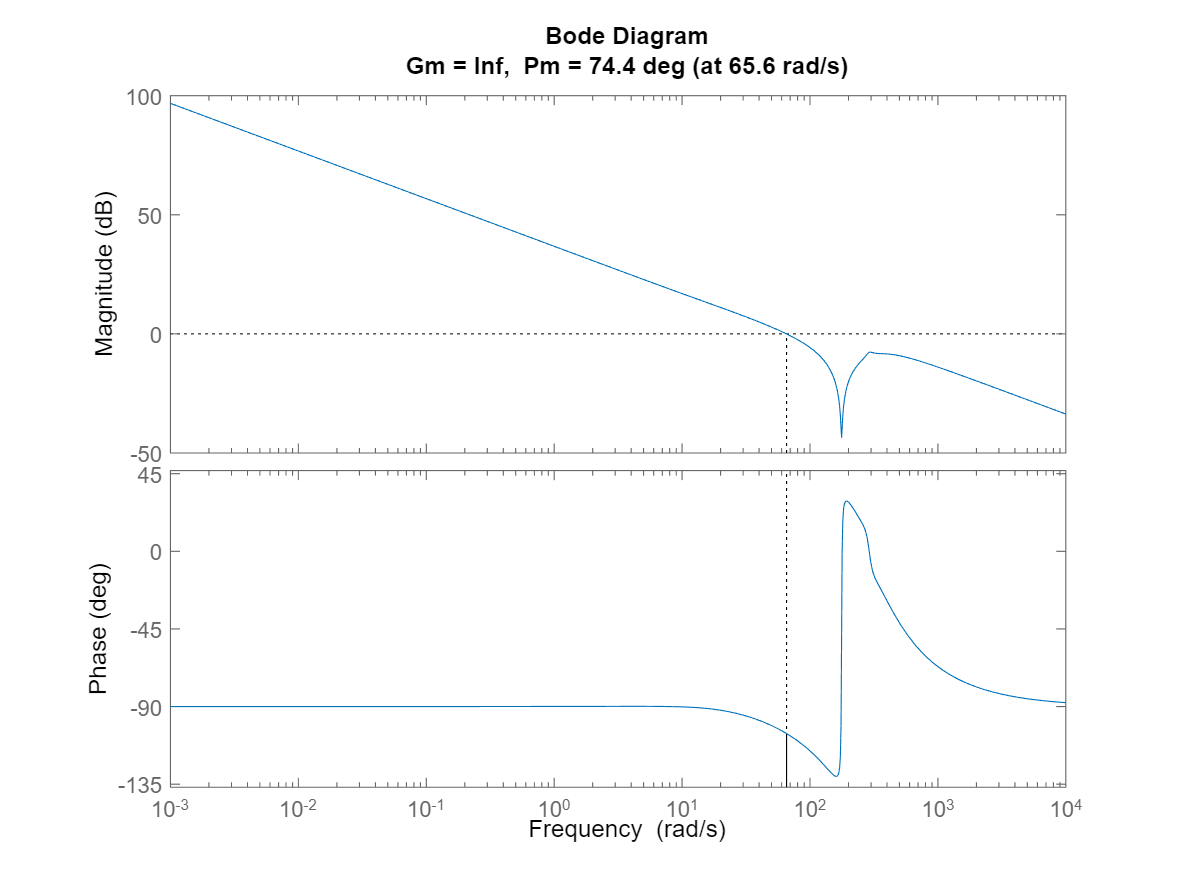

Kp=x(1);
Ki=x(2);
Kd=x(3);
Tf=x(4);
s=tf('s');
C=Kp+Ki/s+Kd*s/(Tf*s+1);

figure(1)
margin(C*P)

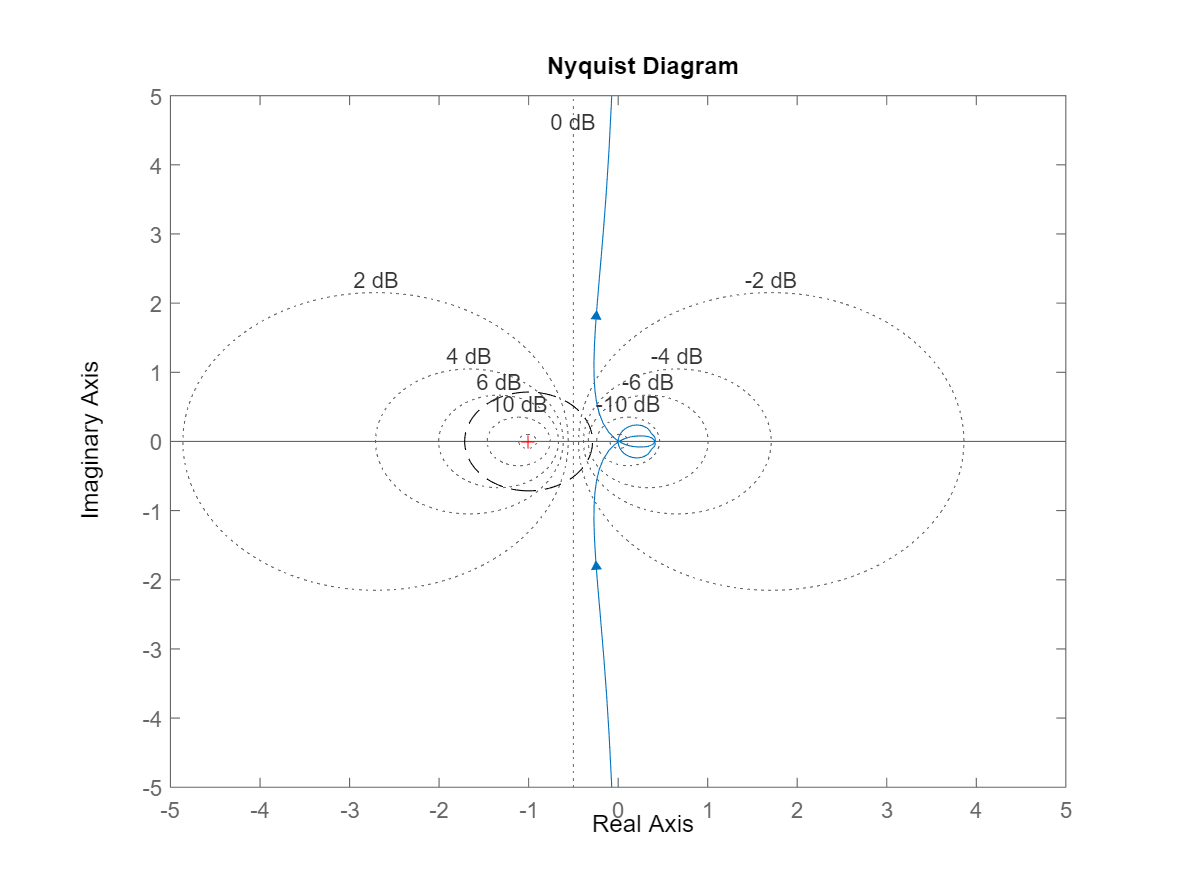

figure(2)
%MS=max(S)=max(1/(1+L)) -> 1/Ms = min(1+L) = min(L-(-1))
nyquist(C*P)
grid on 
hold on
angolo=linspace(-pi,pi);
plot(-1+1/MS*sin(angolo),1/MS*cos(angolo),'--k')
hold off
xlim([-5 5])
ylim([-5 5])